**Teoria de Controle Discreto**

Douglas Lima Militão Pinheiro - 476854

Identificação de um sistema com tanques acoplados

**Da resposta ao degrau, as possibilidades da função de transferência são**

- Um sistema de segunda ordem com polos reais iguais

- Um sistema de primeira ordem

clear 
close all

load("resp_degrau_1.mat")
nivel = resp_degrau.data;
tempo = resp_degrau.time;

k = 4.125;
s = tf('s');

Estimado para uma planta de primeira ordem

tau = 525.4;

G1 = k/(tau*s+1);

Estimado para uma planta de segunda ordem

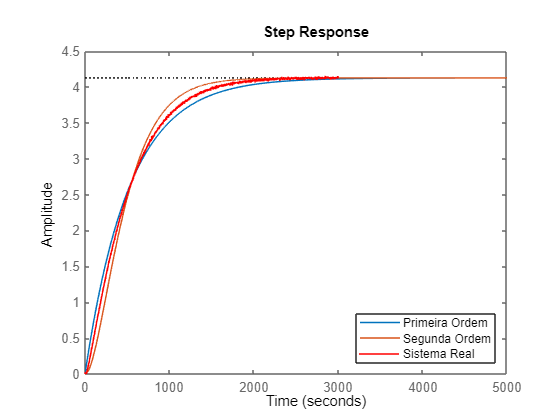

qsi = 1;
wn = 4*10^-3;

G2 = (k*wn^2)/(s^2+2*qsi*wn*s+wn^2);

figure(1)
hold on
step(G1);
step(G2);
plot(tempo,nivel,'r');
legend("Primeira Ordem", "Segunda Ordem", "Sistema Real","Location","southeast");

**Geração do PRBS**

%1/(Tb(2^N - 1)) < f_pbrs < 0,44/Tb
clear
close all

Ts = 40;
Tb = 200;
n = 5;
fmax = 0.44/Tb;
fmin = 1/((2^n - 1)*Tb);
fprintf('Frequência minima - máxima: %fHz - %fHz\nTempo do ensaio mínimo: %ds', fmin, fmax, (2^n - 1)*Tb);

Frequência minima - máxima: 0.000161Hz - 0.002200Hz
Tempo do ensaio mínimo: 6200s

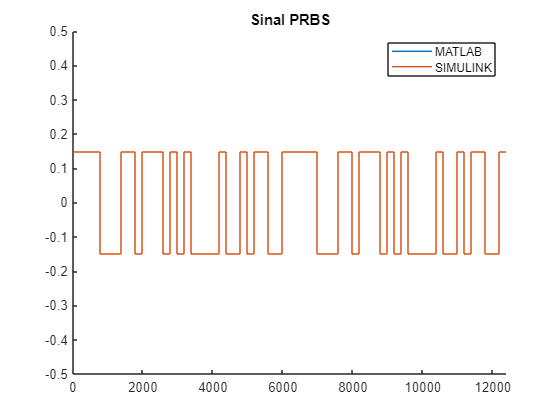

p = [];
base = [0 1 1 1 1];
for i=1:(2^n)
    p = [p base(5)];
    base = [xor(base(3),base(5)) base(1:end-1)];
end

%Duplica para ensaios consecutivos;
p = [p p(2:end)];

for i=1:length(p)
    if (p(i) == 1)
       p(i) = 0.15;
    else
       p(i) = -0.15;
    end
end

%Dados da simulação no simulink
load("ensaio.mat")
entrada_prbs = ensaio((2^n-1)*Tb/Ts+1:end,4);
tempo = ensaio(1:end-(2^n-1)*Tb/Ts,5);

t = 0:Tb:2*(2^n-1)*Tb;

figure(2);
hold on
stairs(t,p);
stairs(tempo, entrada_prbs);
axis([0 t(end) -0.5 0.5]);
legend("MATLAB", "SIMULINK")
title("Sinal PRBS");

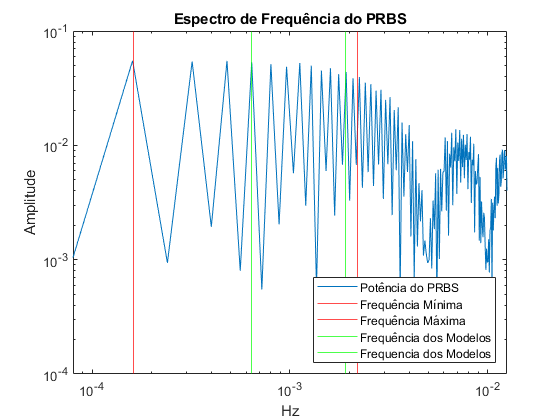

%Transformada de fourier para observação do espectro de frequência
Fs = 1/Ts;
L = length(entrada_prbs)+1;             
Y = fft(entrada_prbs);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

figure(3)
loglog(f(1:end),P1(1:end))
xline([fmin fmax],'r');
xline([1.9*10^-3 6.37*10^-4],'g');
title('Espectro de Frequência do PRBS')
axis([f(1) f(end) 10^-4 10^-1 ])
xlabel('Hz')
ylabel('Amplitude')
legend("Potência do PRBS","Frequência Mínima","Frequência Máxima","Frequência dos Modelos","Frequencia dos Modelos","Location","southeast")

**Identificação do modelo ARX**

clearvars -except n Tb
close all

%Amostragem
Ts = 40;
Tb = 200;
n = 5;

%Dados da simulação no simulink
load("ensaio.mat")
entrada = ensaio(:,1);
nivel = ensaio(:,3);
prbs = ensaio(:,4);
tempo = ensaio(:,5);

%Separa os dados pós inicio da aplicação do prbs
tempo_prbs = tempo((2^n-1)*Tb/Ts+1:end);
prbs = prbs((2^n-1)*Tb/Ts+1:end);
nivel_prbs = nivel((2^n-1)*Tb/Ts+1:end)-nivel((2^n-1)*Tb/Ts)*ones(length(prbs),1);

%Separa 0.75 das amostras para identificação
nIdent = ceil(0.75*length(prbs));
nValid = length(prbs)-nIdent;

entradaIdent = prbs(1:nIdent);
nivelIdent = nivel_prbs(1:nIdent);
tempoIdent = tempo_prbs(1:nIdent);

%Tamanho da matriz de regressores
na = 4; %Quantidade de regressores em y
nb = 4; %Quantidade de regressores em u
k = 0;  %Atraso dos regressores

%Matrizes
Phiy = zeros(length(tempoIdent),na);
Phiu = zeros(length(tempoIdent),nb);

%Criação das matrizes fi e y
for i=max([na nb])+1+k:length(nivelIdent)
    for n1=1:na
        Phiy(i,n1) = -nivelIdent(i-n1);
    end
    for n1=1:nb
        Phiu(i,n1) = entradaIdent(i-n1-k);
    end
    Y(i,1) = nivelIdent(i);
end
fi = [Phiy(max([na nb])+k:end,:) Phiu(max([na nb])+k:end,:)];
Y = Y(max([na nb])+k:end);
teta = (fi'*fi)\fi'*Y;     %Matriz de parâmetros estimados

**Validação do Modelo ARX**

z = tf('z',Ts);
den = 1;
num = 0;

for i=1:na
    den = den + teta(i)*z^-(i);
end
for i=1:nb
    num = num + teta(i+na)*z^-(i+k);
end
nivelValid = nivel_prbs(nIdent+1:end);
entradaValid = prbs(nIdent+1:end);
tsim = 0:Ts:(length(nivelValid)-1)*Ts;
G = num/den

G =
 
     0.08806 z^19 + 0.1278 z^18 + 0.064 z^17 + 0.01584 z^16
  ------------------------------------------------------------
  z^20 - 0.9822 z^19 - 0.2845 z^18 + 0.2047 z^17 + 0.1114 z^16
 
Sample time: 40 seconds
Discrete-time transfer function.



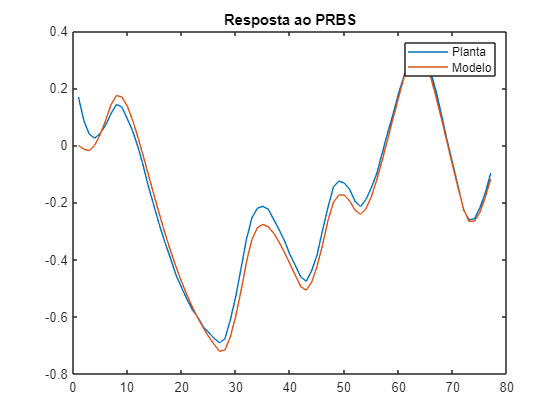

yest = lsim(G,entradaValid,tsim,nivelValid(1));
figure(4)
plot([nivelValid yest]);
title("Resposta ao PRBS");
legend("Planta","Modelo");

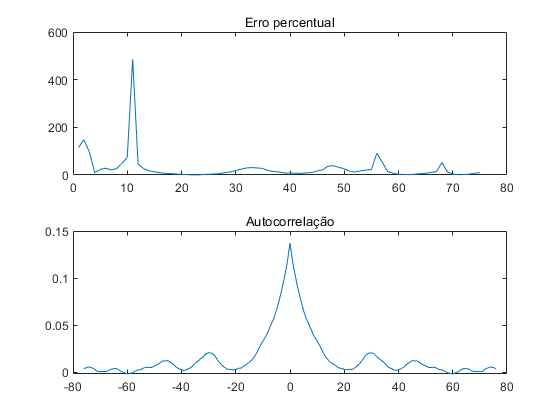

erroabs = abs((nivelValid-yest)./nivelValid)*100;
erro = nivelValid-yest;
[r, c]  = xcorr(erro);
figure(5)
subplot(2,1,1)
plot(erroabs(2:end-1))
subtitle("Erro percentual");
subplot(2,1,2)
plot(c,r)
subtitle("Autocorrelação")

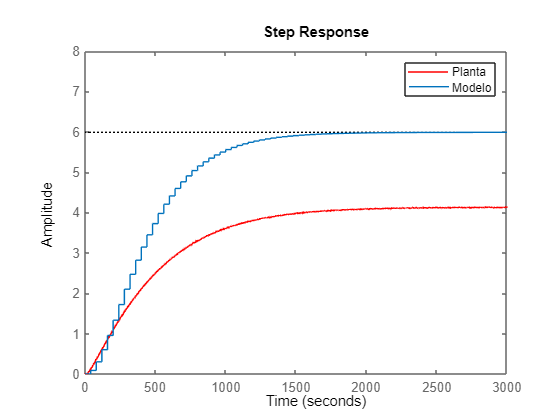

load("resp_degrau_1.mat")
niveldeg = resp_degrau.data;
tempodeg = resp_degrau.time;

figure(6);
hold on
plot(tempodeg,niveldeg,'r');
step(G);
axis([0 3000 0 8]);
legend("Planta","Modelo")

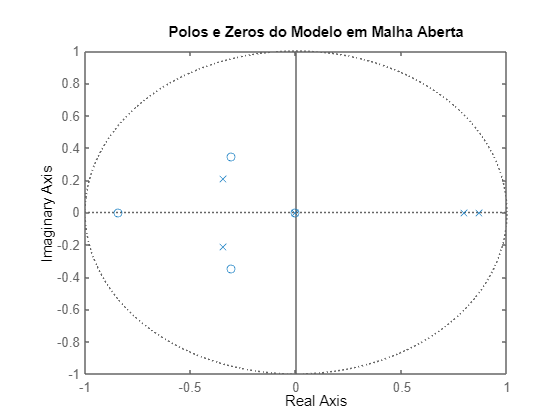

figure(7)
hold on
pzmap(G)

title("Polos e Zeros do Modelo em Malha Aberta")

**Projeto do Controlador RST por alocação de polos**


Gden = cell2mat(G.den);
Gden = Gden(Gden~=0)';
Gnum = cell2mat(G.num);
Gnum = Gnum(Gnum~=0)';

nHs = 1;  % convolução com (1-z^-1)
Gden = conv(Gden,[1 -1]);

nHr = 0; %atraso nHr de todos os regressores

na = length(Gden)-1

na = 5

nb = length(Gnum)+nHr

nb = 4

ns = nb+nHr+k-1

ns = 3

nr = na+nHs-1

nr = 5

np = nb+na+nHs+nHr+k-1

np = 9


M = zeros(na+nb+k);

for i=1:nb+k
    M(:,i) = [zeros(i-1,1); Gden; zeros(nb+k-i,1)]; 
end
for i=1:na
    M(:,i+nb+k) = [zeros(i+nHr,1); Gnum; zeros(na+k-i,1)]; 
end

M

M =     1.0000         0         0         0         0         0         0         0         0
   -1.9822    1.0000         0         0    0.0881         0         0         0         0
    0.6976   -1.9822    1.0000         0    0.1278    0.0881         0         0         0
    0.4892    0.6976   -1.9822    1.0000    0.0640    0.1278    0.0881         0         0
   -0.0933    0.4892    0.6976   -1.9822    0.0158    0.0640    0.1278    0.0881         0
   -0.1114   -0.0933    0.4892    0.6976         0    0.0158    0.0640    0.1278    0.0881
         0   -0.1114   -0.0933    0.4892         0         0    0.0158    0.0640    0.1278
         0         0   -0.1114   -0.0933         0         0         0    0.0158    0.0640
         0         0         0   -0.1114         0         0         0         0    0.0158


**Modelo em Malha Fechada**

    Sistema de segunda ordem com resposta mais rápida para rejeição de perturbação

Tass = 100;
qsi = 1;
wn = 4/(qsi*Tass);
Gmfcont = tf([wn^2],[1 2*qsi*wn wn^2])

Gmfcont =
 
         0.0016
  ---------------------
  s^2 + 0.08 s + 0.0016
 
Continuous-time transfer function.



Gmfdisc = c2d(Gmfcont,Ts,'zoh')

Gmfdisc =
 
     0.4751 z + 0.1619
  ------------------------
  z^2 - 0.4038 z + 0.04076
 
Sample time: 40 seconds
Discrete-time transfer function.



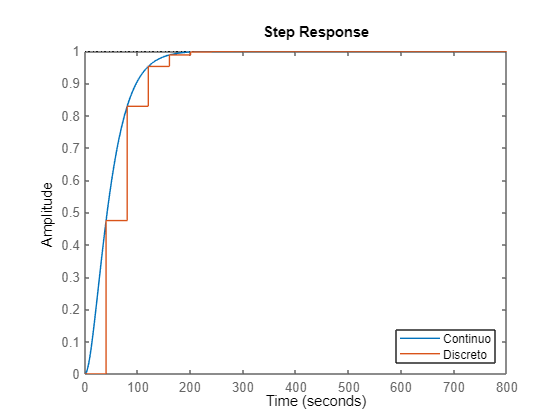


figure(8)
hold on
step(Gmfcont)
step(Gmfdisc)
legend("Continuo","Discreto",'Location','southeast')

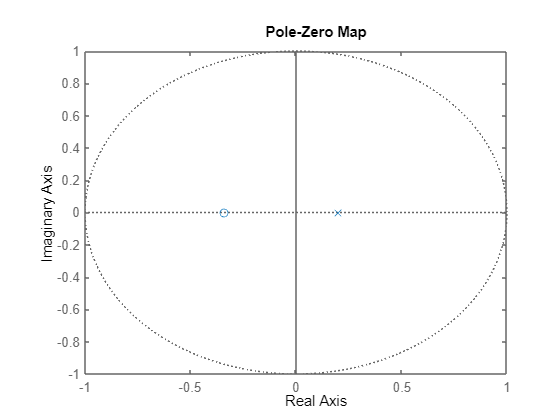

figure(9)
pzmap(Gmfdisc)

qtdpdom = length(cell2mat(Gmfdisc.den))-1

qtdpdom = 2

qtdpaux = np-qtdpdom

qtdpaux = 7


regpaux = 0;

p = cell2mat(Gmfdisc.den);

for i=1:qtdpaux-1
    p = conv(p,[1 -regpaux*rand()]);
end
p = p' 

p =     1.0000
   -0.4038
    0.0408
         0
         0
         0
         0
         0
         0


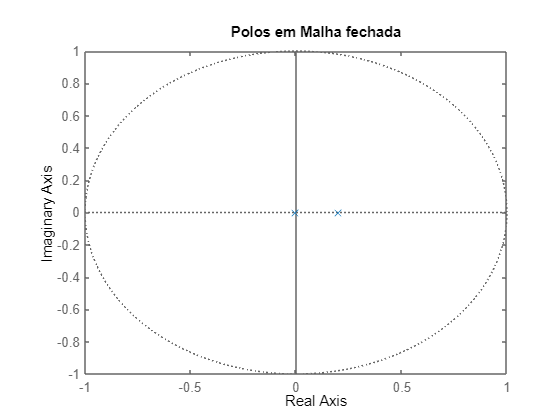

Gaux = tf(1,p',Ts);
figure(10)
pzmap(Gaux)
title("Polos em Malha fechada")

RS = M\p

RS =     1.0000
    0.8886
    0.4479
    0.0890
    7.8337
   -3.9118
   -3.5398
    1.1464
    0.6258


S = conv(RS(1:ns+1),[1 -1])'

S =     1.0000   -0.1114   -0.4406   -0.3590   -0.0890


R = RS(ns+2:end)'

R =     7.8337   -3.9118   -3.5398    1.1464    0.6258


Tnum = p'

Tnum =     1.0000   -0.4038    0.0408         0         0         0         0         0         0


B1 = sum(cell2mat(G.num))

B1 = 0.2957

**Modelo em Malha Fechada**

    Sistema de segunda ordem com resposta mais lenta para rastreamento

Tass = 400;
qsi = 1;
wn = 4/(qsi*Tass);
Gmfcont = tf([wn^2],[1 2*qsi*wn wn^2])

Gmfcont =
 
         0.0001
  ---------------------
  s^2 + 0.02 s + 0.0001
 
Continuous-time transfer function.




z = tf('z',Ts);

Gmfdisc = c2d(Gmfcont,Ts,'zoh')

Gmfdisc =
 
   0.06155 z + 0.04714
  ----------------------
  z^2 - 1.341 z + 0.4493
 
Sample time: 40 seconds
Discrete-time transfer function.




Gmfdisc = Gmfdisc*z^-(k+1)

Gmfdisc =
 
     0.06155 z + 0.04714
  --------------------------
  z^3 - 1.341 z^2 + 0.4493 z
 
Sample time: 40 seconds
Discrete-time transfer function.




Bm = cell2mat(Gmfdisc.num)

Bm =          0         0    0.0616    0.0471


Am = cell2mat(Gmfdisc.den)

Am =     1.0000   -1.3406    0.4493         0
